# MA438 Lab 6: Nonnegative matrix factorization

clear;

## 1. The motivating example

We'll take the data from Table 2 of [[https://arxiv.org/pdf/1706.09699.pdf](https://arxiv.org/pdf/1706.09699.pdf)], and store it in the matrix $A$.

A = [
   4 5 4 1;
5 5 5 1;
5 3 2 2;
4 2 1 5;
5 1 1 5];

First, let's check the rank of this matrix, and its singular values

s = svd(A)

So we see it has full rank, but the first two signular values are much larger that then rest. So it is reasonable to expect that we can make a useful Rank 2 approximation.

But first, make the rank-1 NNMF. This is done with the nnmf() function. It is part of the "Statistics and Machine Learning" toolbox. If you don't have that installed, use the on-line version at

[https://matlab.mathworks.com](https://matlab.mathworks.com)

## 2. Using nnmf()

Recall that a nonnegative matrix factorization of a matrix, $A$, is a pair of matrices, $W$ and $H$, such that

- $W$ and $H$ are no negative entries

- If $A$ is $m \times n$, then $W$is $m \times r$ and $H$ is $r \times n$, where $r$ is the rank of the factorisation

- $WH \approx A$  (but we expect $WH \neq A$, and so $\|A-WH\|>0$).

### 2.1 A Rank-1 Approximation

[W1,H1] = nnmf(A,1)

Now we'll check how similar $A$ is to $W_1H_1$. We see that the entries of $A-W_1H_1$ are not particularly small.

A-W1*H1

Better: compute the norm $\|A - W_1H_1\|_F$

Error1=norm(A-W1*H1, 'fro')

### 2.2 A Rand 2 approximation

Now try a Rank 2 approximation

[W2,H2] = nnmf(A,2)

Again compute the difference, and its norm:

A-W2*H2
Error2=norm(A-W2*H2, 'fro')

Finally, rank 3 and 4. We won't look at the details, just the errors/differences. Interestingly, the Rank 3 version actually returns a rank 2 appromimation.

[W3,H3] = nnmf(A,3);
A3=W3*H3;
Error3=norm(A-A3, 'fro')
[W4,H4] = nnmf(A,4);
A4=W4*H4;
Error4=norm(A-A4, 'fro')

## 3. Visualising the factorization

Let's focus on the $r=2$ factorization:

biplot(H2', 'scores', W2, 'VarLabels',...
   {'Alice','Becky','Cindy','Dora'});
axis([0 1 0 1])
xlabel('Funny')
ylabel('Scary')

## 4. Our own example from Lab 3

This is based on data we worked on in Lab 3, but is complete (no missing data). Also we'll reduce to just two categories. We want to see if we can cluster our people and TV shows.

fprintf("4: Our own example\n --------------------\n")
Shows = {'Octonauts', 'Puffin Rock',  ...
   'Match of The Day', 'The Sunday Game'}
Users = {'Ann', 'Barry', 'Cath', 'Donny', 'Eddie', 'Fiona'}

And this is our recommender matrix:

R = [9     9     2     1;
     8     7     2     3;
     3     5     4     5;
     5     3     1     2;
     3     5     8     9;
     1     1     9     7];

Let's check its singular values:

s = svd(R)

So it looks like Rank 2 would be good:

[W2,H2] = nnmf(R,2)
Error2=norm(R-W2*H2, 'fro')

To intrepret this data - for a Rank 2 approximation, we can think of the entries of $W$representing how strongly each of the 6 users identifies with each of the two programme types (so it is an $6 \times 2$ matrix).

Similarly $H$ tells us how, for each of the $4$ programme types, how much they are appealed to  by the two different types of user.

There are a few ways to visualise this, e.g., as a "biplot".

biplot(H2', 'scores', W2, 'VarLabels', Shows);
axis([0 1 0 1])
xlabel('Kid')
ylabel('Adult')

We could also look at this with a standard plot:

plot(1:6, W2(:,1), '--s', 1:6, W2(:,2), '--o', ...
   'LineWidth',2)
legend('Programe Type 1', 'Programe Type 2', 'Location','north');
set(gca,'xtick', 1:6,'xticklabel',Users);
plot(1:4, H1(1,:), '--s', 1:4, H2(2,:), '--o', ...
   'LineWidth',2)
legend('Person Type 1', 'Person Type 2', 'Location','north');
set(gca,'xtick', 1:6,'xticklabel', Shows);

## 5. Computing W and H

(This part is based on the "Suplementary Advanced Material" on p12 of the paper. You can skip it if you like). One can compute $W$ and $H$ iteratively. Start with a guess of 2 positive matrices, $h$ and $w$ of the correct size:

fprintf("5: Computing W and H\n")
[m,n] = size(R);
r = 2; % rank of approximation
w = rand(m,r); 
h = rand(r,n); 

Since these are random, they should have the right rank. Let's check:

rank(w)
rank(h)

The formula for the iteration is

 h = h.*((w'*R)./(w'*w*h));
 w = w.*( (R*h')./(w*h*h'));
 w=w/diag(sum(w));

 We can repeat this...

for k=1:20
   h = h.*((w'*R)./(w'*w*h));
   w = w.*( (R*h')./(w*h*h'));
   w=w/diag(sum(w));
   disp([k, norm(R-w*h)]);
end
biplot(H2', 'scores', W2, 'VarLabels', Shows);
axis([0 1 0 1])
xlabel('Kid')
ylabel('Adult')

## Exercises 3.10 from Problem Set 3

*This is an exercise from Problem Set 3. *

 Consider the graph  showing in the following image.

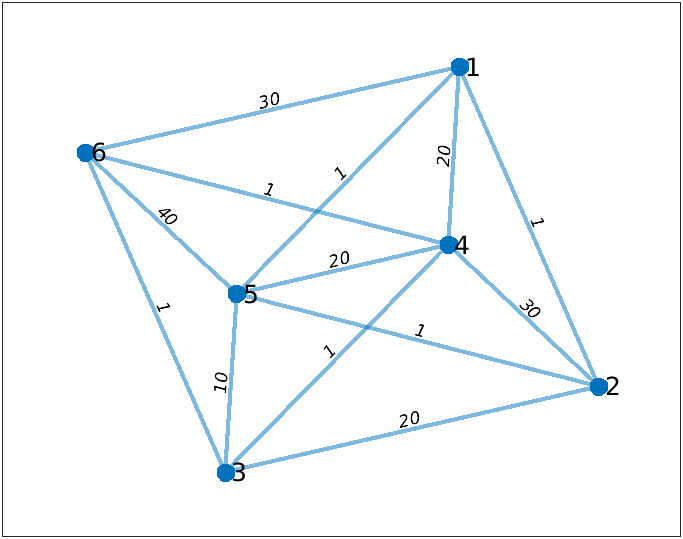

- Write down the weighted adjacency matrix, $A$, for this graph, and store it as a matrix in MATLAB.

- Using MATLAB's `nnmf()` function, compute the rank 2 nonnegative matrix factorization of $A$. 

- Use the information represented by the nonnegative matrix factorization to classify the vertices in the graph into one of two types. Give an intrpretation of this classification.